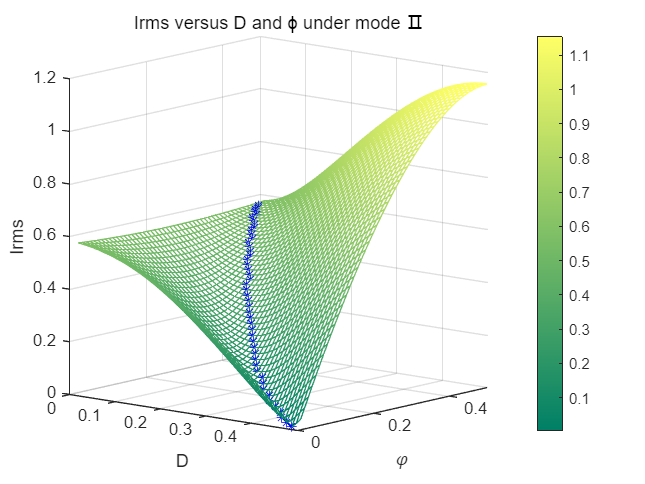

minpeaks = -0.0047

minlocs = 48

minpeaks = -0.0131

minlocs = 46

minpeaks = -0.0240

minlocs = 44

minpeaks = -0.0355

minlocs = 43

minpeaks = -0.0477

minlocs = 41

minpeaks = -0.0622

minlocs = 39

minpeaks = -0.0763

minlocs = 38

minpeaks = -0.0920

minlocs = 36

minpeaks = -0.1073

minlocs = 35

minpeaks = -0.1236

minlocs = 34

minpeaks = -0.1402

minlocs = 32

minpeaks = -0.1565

minlocs = 31

minpeaks = -0.1731

minlocs = 30

minpeaks = -0.1899

minlocs = 29

minpeaks = -0.2067

minlocs = 28

minpeaks = -0.2235

minlocs = 27

minpeaks = -0.2401

minlocs = 26

minpeaks = -0.2566

minlocs = 25

minpeaks = -0.2730

minlocs = 24

minpeaks = -0.2891

minlocs = 23

minpeaks = -0.3050

minlocs = 22

minpeaks = -0.3207

minlocs = 21

minpeaks = -0.3361

minlocs = 20

minpeaks = -0.3512

minlocs = 19

minpeaks = -0.3661

minlocs = 18

minpeaks = -0.3807

minlocs = 17

minpeaks = -0.3947

minlocs = 17

minpeaks = -0.4084

minlocs = 16

minpeaks = -0.4217

minlocs = 15

minpeaks = -0.4347

minlocs = 14

minpeaks = -0.4473

minlocs = 13

minpeaks = -0.4592

minlocs = 13

minpeaks = -0.4707

minlocs = 12

minpeaks = -0.4819

minlocs = 11

minpeaks = -0.4926

minlocs = 10

minpeaks = -0.5026

minlocs = 10

minpeaks = -0.5121

minlocs = 9

minpeaks = -0.5211

minlocs = 8

minpeaks = -0.5296

minlocs = 8

minpeaks = -0.5373

minlocs = 7

minpeaks = -0.5445

minlocs = 6

minpeaks = -0.5512

minlocs = 5

minpeaks = -0.5570

minlocs = 5

minpeaks = -0.5622

minlocs = 4

minpeaks = -0.5668

minlocs = 3

minpeaks = -0.5705

minlocs = 3

minpeaks = -0.5734

minlocs = 2


minpeaks =

  空的 1×0 double 行向量


minlocs =

  空的 1×0 double 行向量



错误使用 plot3
向量长度必须相同。

[x,y]=meshgrid(0.01:0.01:0.5,0.01:0.01:0.5);
mesh(x,y,irms)
xlim([0,0.5]);
ylim([0,0.5]);
%plot(phi,irms(phi,D))
%plot3(x,y,irms)
shading interp %这是阴影上色的关键
colormap summer
colorbar
title('Irms versus D and ϕ under mode Ⅱ')
ylabel('𝜑') %设置纵坐标轴
xlabel('D') %设置横坐标轴
zlabel('Irms')
hold on
grid on
view(40,10)
%view(-160,45)


%[peaks,locs]=findpeaks(irms30)%findpeaks用于找凸函数的最大值
for D=1:100
    [minpeaks,minlocs]=findpeaks(-irms(D,:))
    plot3(y(minlocs),D/100,-minpeaks,'b*');
    hold on;
    %view(35,10)
    %view(-160,45)
end



%mesh(x(locs),y(locs),irms);


% fitModel = fit(t_uni', transpose(I_point(index1)), 'linearinterp');%拟合三位曲线函数，较复杂，先换一种求极值方式
% initialGuess=[0,0];%初始猜测点
% options =optimset('Display','iter');% 设置显示迭代过程
% optimalPoint =fminsearch(@(p)-fitModel(p(1),p(2)),initialGuess, options);

